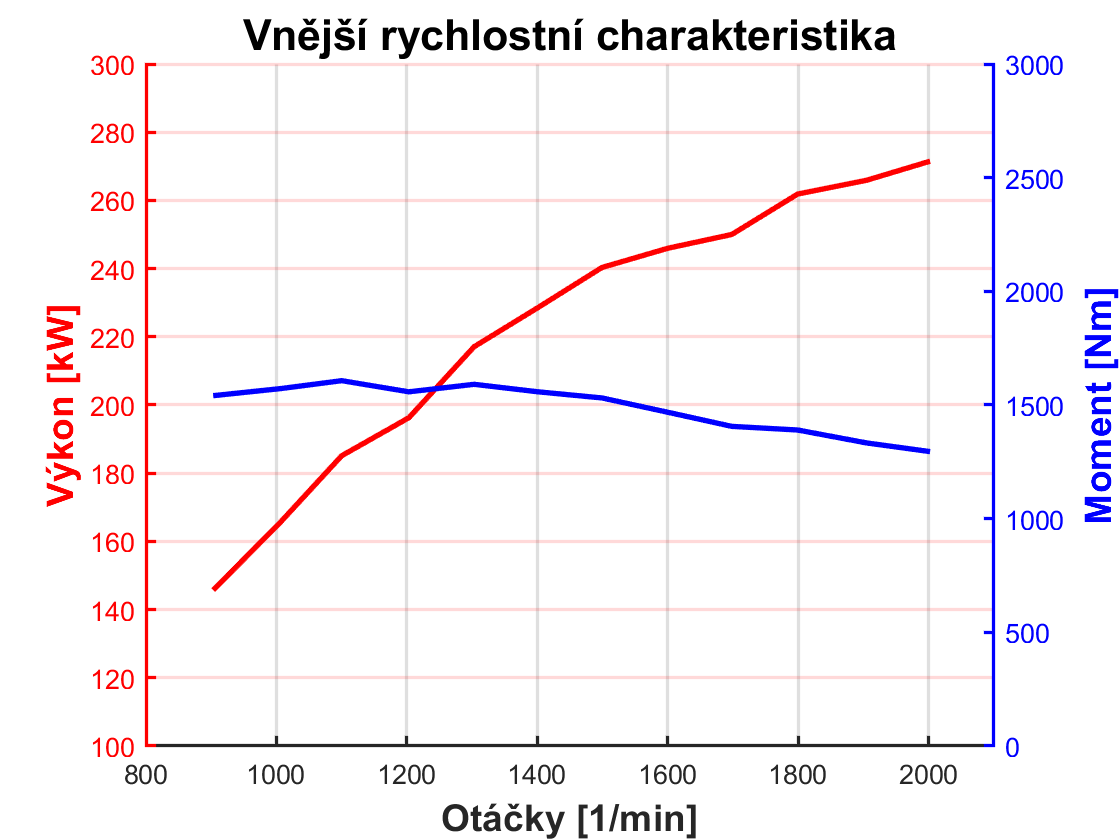

OtackyM1 = [903;1006;1100;1203;1303;1401;1499;1600;1698;1799;1905;2002];
MomentM1 = [1541;1572;1607;1558;1591;1558;1531;1468;1406;1390;1333;1295];
%PowerM1 = [145.6;165.5;185.1;196.2;217;228.6;240.3;246;250.1;261.9;265.9;271.6];
SpotrebaMM1 = [249.4;234.8;228.3;224.2;218;215.9;214.6;215.2;216;217.1;221.5;223.9];
SpotrebaM1 = [36.31;38.86;42.26;43.99;47.31;49.35;51.57;52.94;54.02;56.86;58.90;60.81];

%36342.5549821616
%38884.5639335669
%42261.3232698427
%44004.5219076620
%47325.9899253289
%49349.9649926988
%51574.5157760754
%52931.8317295522
%54001.4443348927
%56850.5152330856
%58901.6523325148
%60787.8178043595

Otacky = [2000;2500;3000;4000;4500;5000;5250;5500];
Moment = [105;104;103.5;102;98;89;84;79];
%Otacky = [1421;1595;1770;1418;1545];
%Moment = [912.357;919.360;882.405;852.923;828.587];
%PlniciTlak = [248;264;270;256;264];
figure;
set(gca, 'linewidth',1.2);
title('Vnější rychlostní charakteristika','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
Vykon = (2*pi/60).*OtackyM1.*MomentM1;
MernaSpotreba = kg2g(SpotrebaM1)./W2kW(Vykon);
hold on
yyaxis left
plot(OtackyM1, W2kW(Vykon),'-r','linewidth',2)
yyaxis right
plot(OtackyM1, MomentM1,'-b','linewidth',2)
hold off
grid on;
%legend('\kappa = 1,67','\kappa = 1,41','\kappa = 1,3')
hold off;
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([800 2100]);
yyaxis left;
ylim([100 300]);
ylabel('Výkon [kW]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','r');
yyaxis right;
ylim([0 3000]);
ylabel('Moment [Nm]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','b');

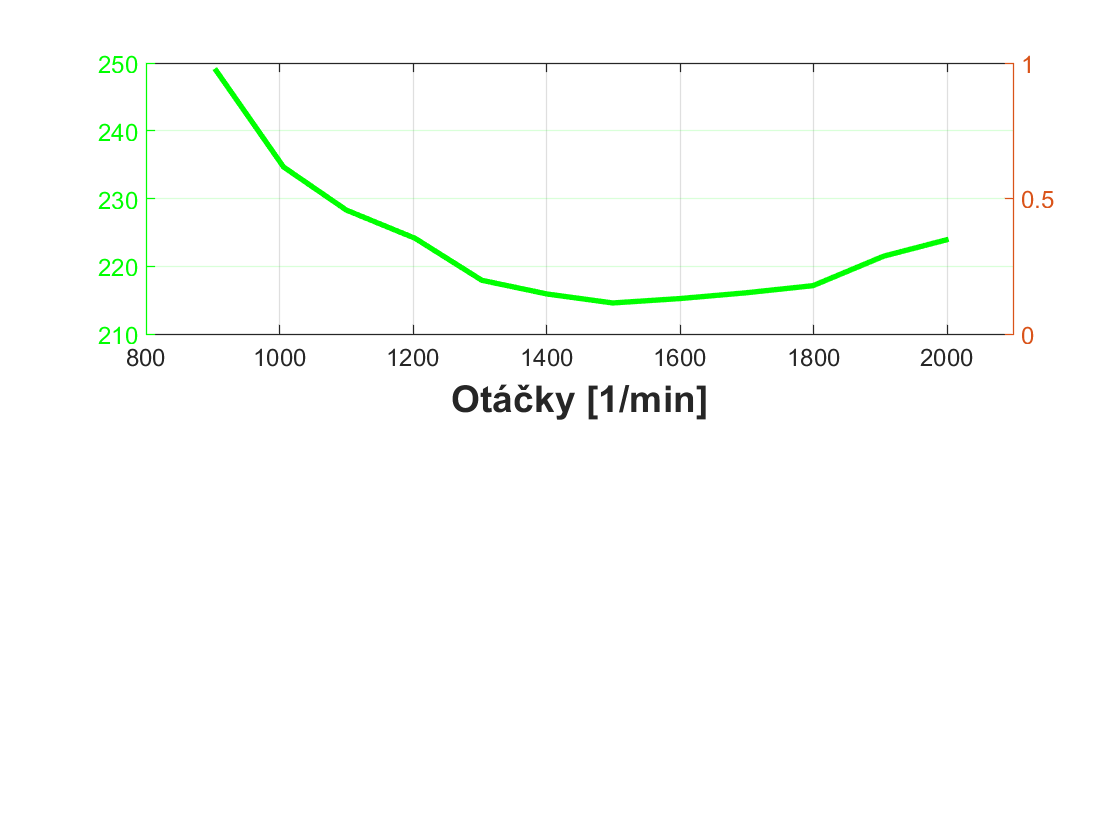

figure;
subplot(2,1,1);
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([800 2100]);
yyaxis left;
ylim([180 300]);
ylabel('Měrná spotřeba [g/kgh]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','g');
plot(OtackyM1,MernaSpotreba,'-g','linewidth',2);
grid on;

### Vyhlazený graf vnější rychlostní charakteristiky

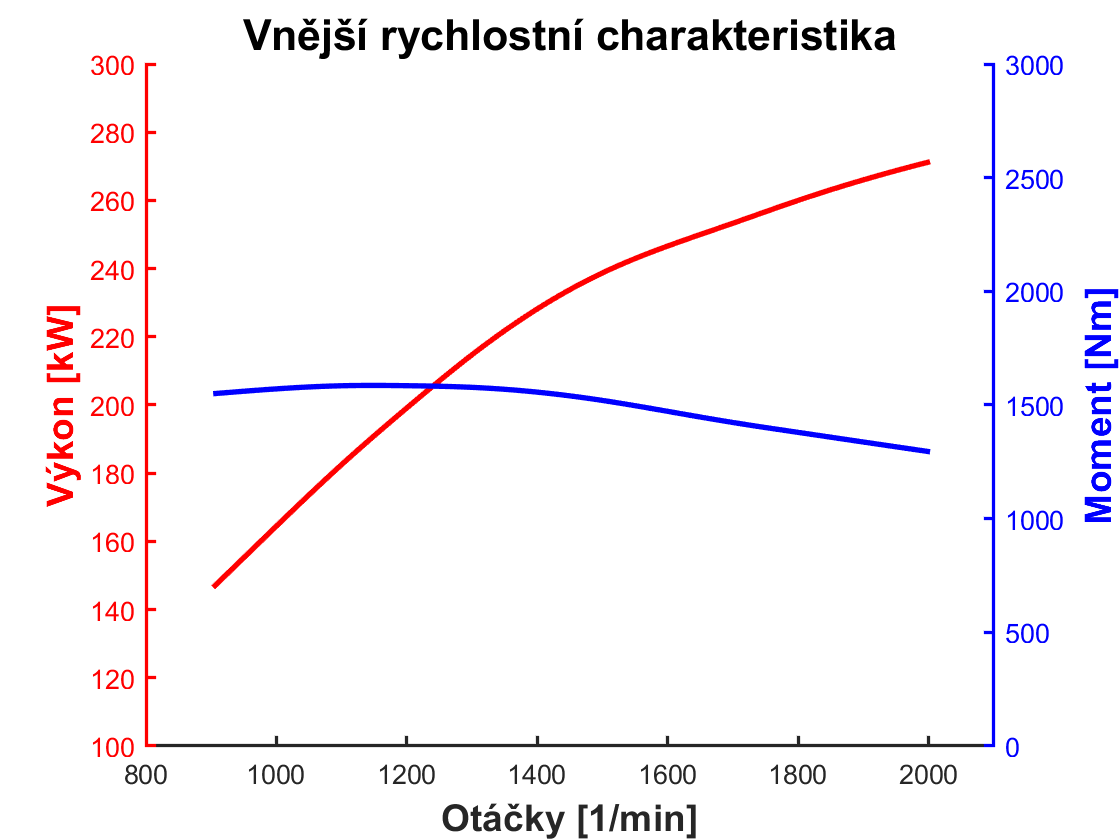

figure;
set(gca, 'linewidth',1.2);
title('Vnější rychlostní charakteristika','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
%p = polyfit(OtackyM1,MomentM1,6);
%figure;
[ii,jj] = size(OtackyM1);
OtackyJemne  = linspace(OtackyM1(1),OtackyM1(ii),100);
%MomentJemne = polyval(p,OtackyJemne);
yy = zeros(length(OtackyJemne));
p = 0.000001;
   MomentJemne = csaps(OtackyM1,MomentM1,p,OtackyJemne);
VykonJemne = (2*pi/60).*OtackyJemne.*MomentJemne;   
hold on
yyaxis left
plot(OtackyJemne, W2kW(VykonJemne),'-r','linewidth',2)
yyaxis right
plot(OtackyJemne, MomentJemne,'-b','linewidth',2)
hold off;
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([800 2100]);
yyaxis left;
ylim([100 300]);
ylabel('Výkon [kW]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','r');
yyaxis right;
ylim([0 3000]);
ylabel('Moment [Nm]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','b');

%plot(OtackyM1,MomentM1,'o');
%plot(OtackyJemne,MomentJemne);


### Lokální funkce 

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod kg

function [g] = kg2g(kg)
g = kg * 1000.0;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end